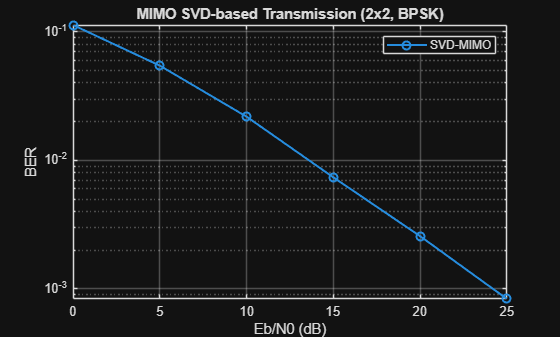

clc; clear; close all;

% Parameters
Nt = 2;              % Transmit antennas
Nr = 2;              % Receive antennas
N  = 1e5;            % Number of symbols
EbN0_dB = 0:5:25;

% BPSK symbols
bits = randi([0 1], Nt*N, 1);
symbols = 2*bits - 1;
symbols = reshape(symbols, Nt, []);

ber = zeros(size(EbN0_dB));

for i = 1:length(EbN0_dB)
    
    EbN0 = 10^(EbN0_dB(i)/10);
    noise_var = 1/(2*EbN0);
    
    error = 0;
    total = 0;
    
    for k = 1:N
        
        % Generate Rayleigh MIMO channel
        H = (randn(Nr,Nt) + 1j*randn(Nr,Nt))/sqrt(2);
        
        % SVD decomposition
        [U, S, V] = svd(H);
        
        % Transmit symbol
        s = symbols(:,k);
        
        % Precoding (Tx)
        x = V * s;
        
        % Noise
        n = sqrt(noise_var)*(randn(Nr,1) + 1j*randn(Nr,1));
        
        % Channel
        y = H*x + n;
        
        % Receiver processing
        y_tilde = U' * y;
        
        % Effective diagonal channel
        r = y_tilde ./ diag(S);
        
        % Detection
        s_hat = real(r) > 0;
        
        % Count errors
        error = error + sum(s_hat ~= (s > 0));
        total = total + Nt;
    end
    
    ber(i) = error / total;
end

% Plot
figure;
semilogy(EbN0_dB, ber, 'o-', 'LineWidth', 1.5);
grid on;
xlabel('Eb/N0 (dB)');
ylabel('BER');
title('MIMO SVD-based Transmission (2x2, BPSK)');
legend('SVD-MIMO');